# MEMS 1045 Week 2 Assignment

## Problem 1

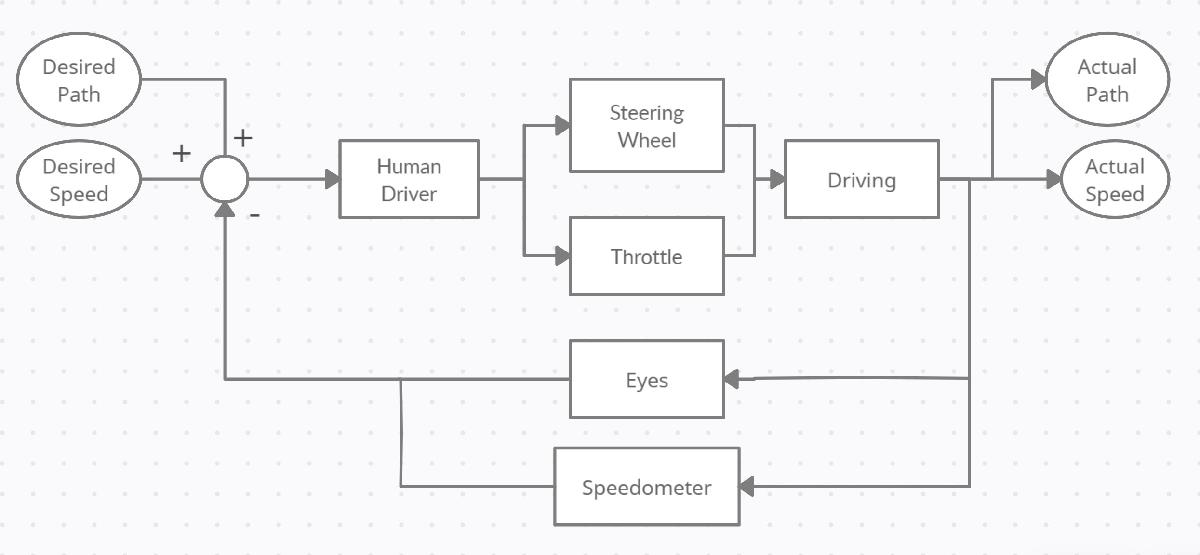

## Problem 2

(a) thermocouple

(b) pressure transducer

(c) capacitance level sensor

(d) Pitot tube

(e) linear variable differential transformer

(f) incremental/rotary encoder

(g) linear velocity transducer

(h) magnetoresistive sensor

(i) piezoelectric accelerometer

(j) torque transducer

## Problem 3

Feedback connection:


$$\frac{e_4}{e_2}=\frac{forward\:path}{1 + loop\:gain}=\frac{B}{1+BH}$$


Series connection:


$$\frac{e_4}{e_1}=A*\frac{B}{1+BH}=\frac{AB}{1+BH}$$


Parallel connection:


$$\frac{y}{e_1}=\frac{AB}{1+BH}+D$$


Feedback connection:


$$\frac{Y}{R}=\frac{\frac{AB}{1+BH}+D}{1+G(\frac{AB}{1+BH}+D)}=\frac{AB+D(1+BH)}{(1+BH)+GAB+GD(1+BH)}$$


Transfer Function: $\frac{\textbf{Y}}{\textbf{R}}=\frac{\textbf{AB+D+DBH}}{\textbf{1+BH+GAB+GD+GDBH}}$

## Problem 4

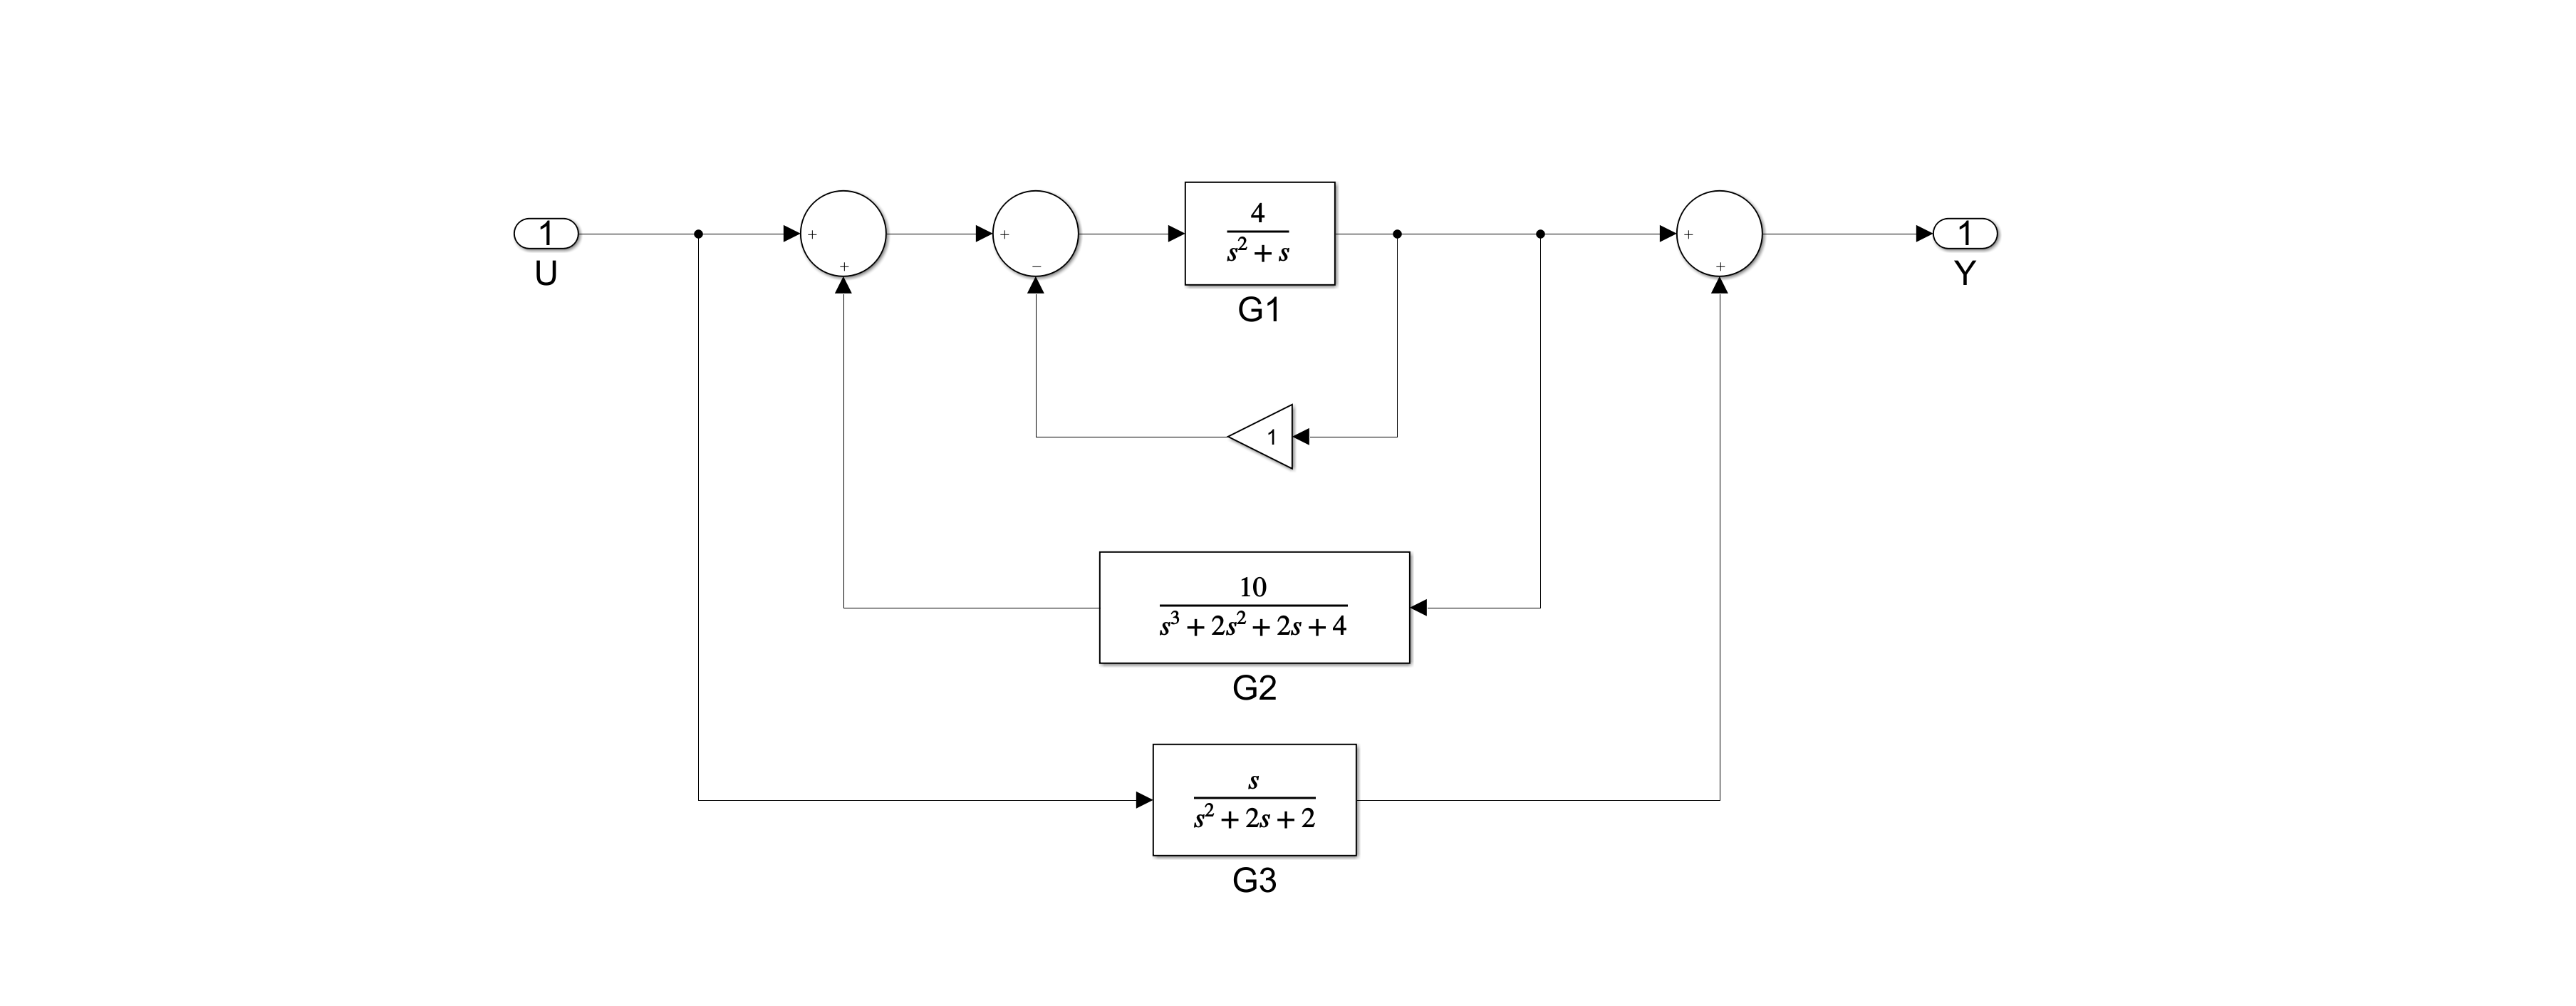

To find the overall transfer function of this block diagram, we can work from the inside out. First, we can find the transfer function sysG4 for the negative feedback loop involving $G_1
$. Next, we calculate the transfer function sysG5 for the positive feedback loop involving sysG4 and $G_2$. Finally, the overall transfer function $\frac{Y}{U}$ (sysCL) is found by simplifying the parallel connection between $G_3$ and sysG5.

s = tf('s');
sysG1 = 4/(s*(s+1));
sysG2 = 10/((s+2)*(s^2+2));
sysG3 = s/(s^2+2*s+2);

sysG4 = feedback(sysG1,1,-1);

sysG5 = feedback(sysG4,sysG2,+1);

sysCL = parallel(sysG3,sysG5)

sysCL =
 
                                         
  s^6 + 7 s^5 + 24 s^4 + 46 s^3          
                                         
                     + 60 s^2 + 24 s + 32
                                         
  ---------------------------------------
                                         
  s^7 + 5 s^6 + 16 s^5 + 36 s^4          
                                         
            + 56 s^3 + 28 s^2 - 24 s - 48
                                         
 
Continuous-time transfer function.



To determine if the system is stable, we can plot the pole-zero map for the transfer function and determine if any poles/zeroes fall in the right half plane.

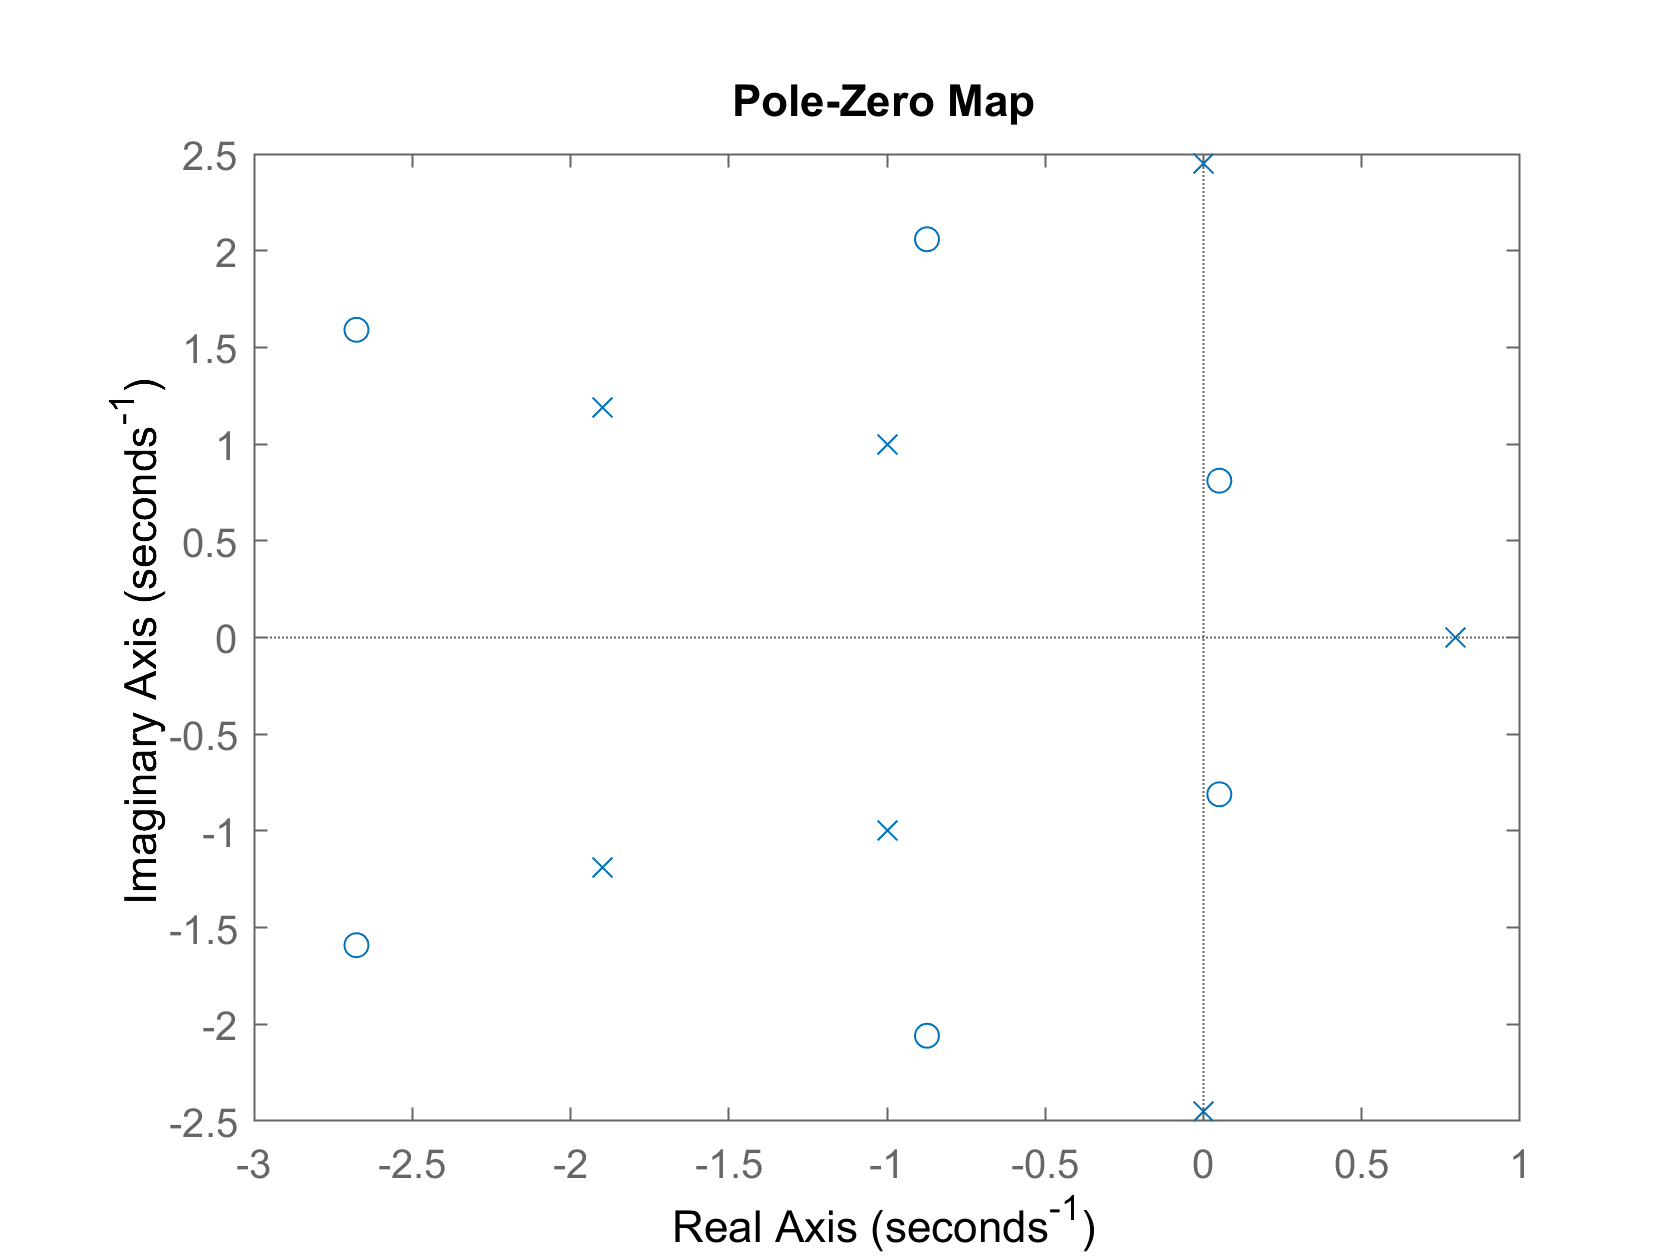

pzmap(sysCL)

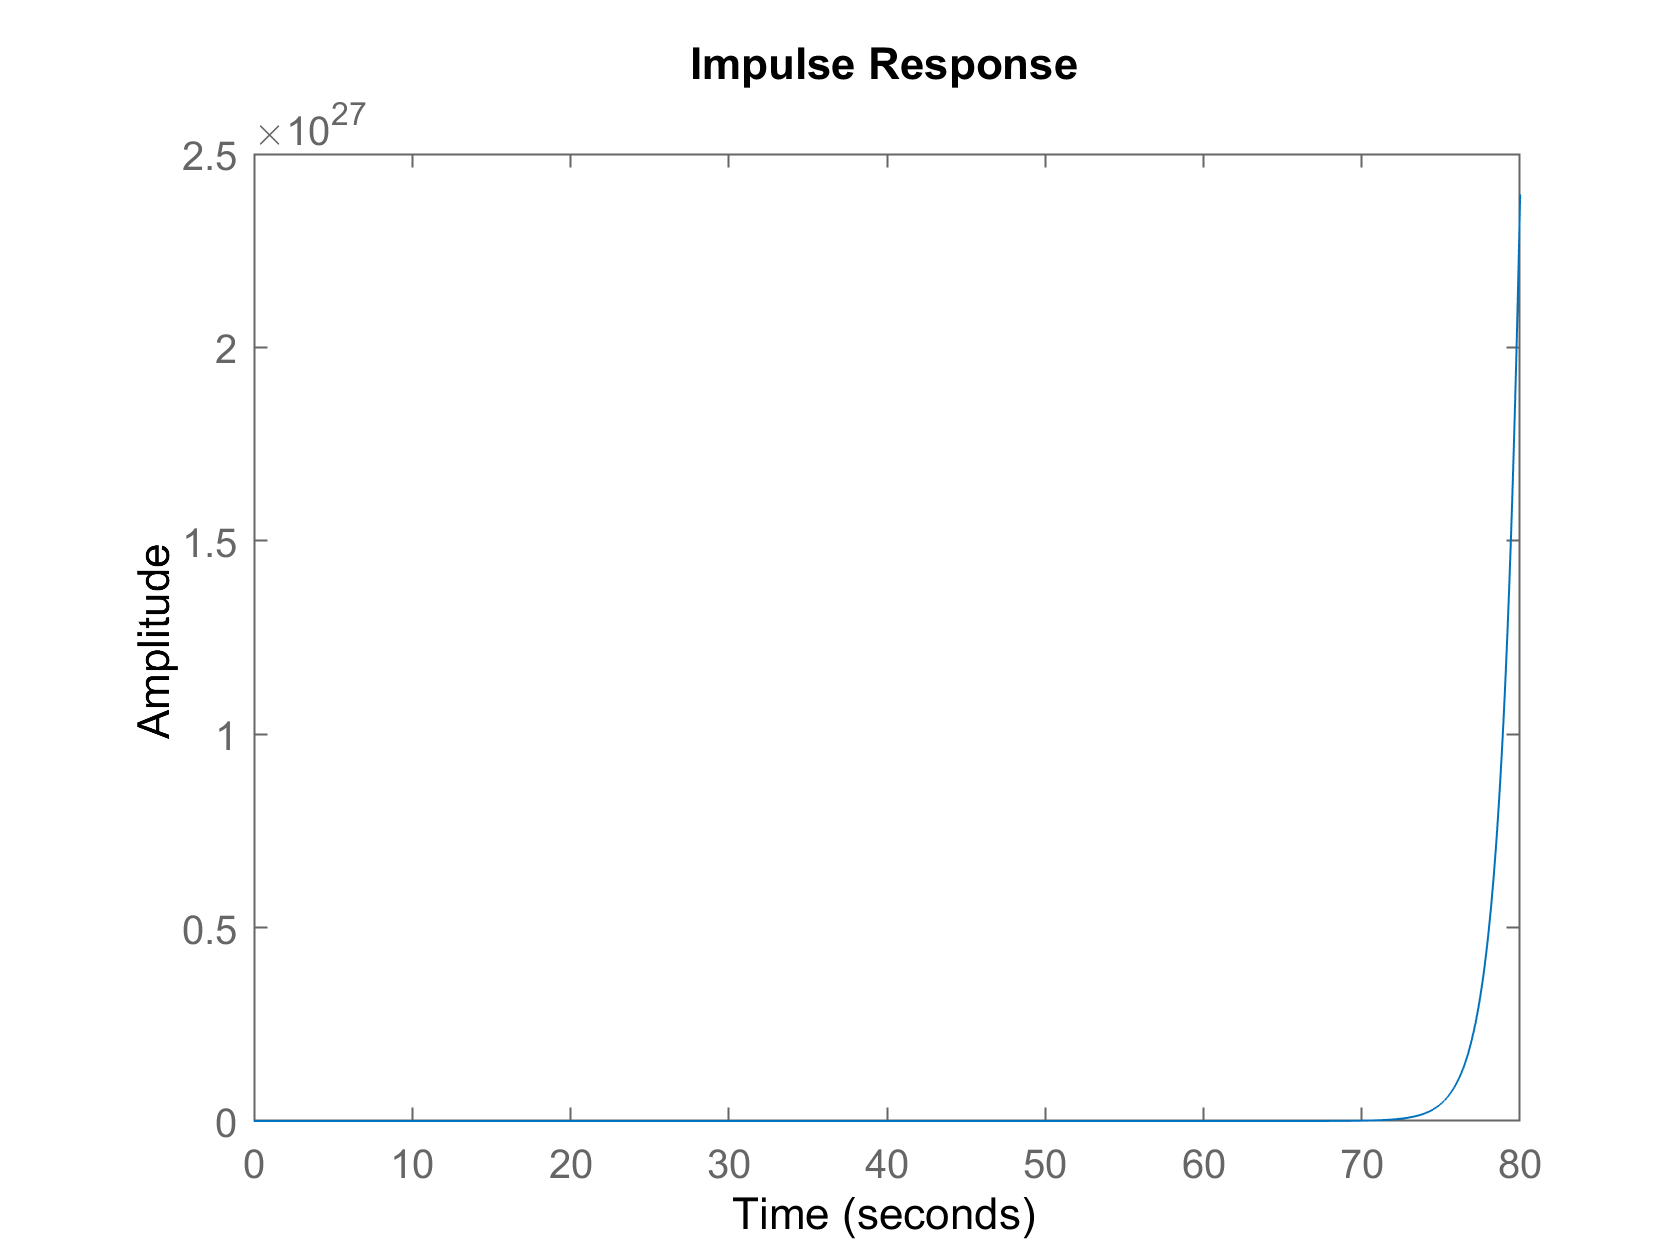

impulse(sysCL)

Given the pole-zero map and impulse response plot shown above, it's clear that the system is **unstable**. This is shown by the poles and zeroes in the right half plane as well as the exponentially growing impulse response of the system.

## Problem 5

Calculate the transfer function $\frac{V_2(S)}{V_1(s)}$:


$$V_2(s)=\frac{1}{Cs}I(s)$$



$$V_1(s)=(Ls+R+\frac{1}{Cs})I(s)$$



$$\frac{V_2(s)}{V_1(s)}=\frac{\frac{1}{Cs}I(s)}{(Ls+R+\frac{1}{Cs})I(s)}=\frac{\textbf{1}}{\textbf{LC$s^2$
+RCs+1}}$$


Find the damping ratio $\zeta$and the undamped natural frequency $\omega_n$:


$$s^2+2\zeta\omega_ns+\omega_n^2=s^2+\frac{R}{L}s+\frac{1}{LC}$$



$$\omega_n^2=\frac{1}{LC}$$



$$\omega_n=\sqrt{\frac{\textbf{1}}{\textbf{LC}}}$$



$$2\zeta\omega_n=2\zeta(\frac{1}{\sqrt{LC}})=\frac{R}{L}$$



$$\zeta=\frac{\textbf{R}\sqrt{\textbf{LC}}}{\textbf{2L}}$$


## Problem 6


$$\frac{Y}{R}=\frac{forward\:path}{1+loop\:gain}=\frac{\frac{100K}{(s+a)(s+25)}}{1+\frac{100K}{(s+a)(s+25)}}$$


Multiply the numerator and denominator of the fraction by the denominator of the loop gain to simplify the transfer function.


$$\frac{Y}{R}=\frac{100K}{(s+a)(s+25)+100K}=\frac{100K}{s^2+(25+a)s+(25a+100K)}$$


Now we can use the denominator of this transfer function to calculate the values of $a$ and $K$using the given values of $\omega_n$ and $\zeta$.


$$s^2+2\zeta\omega_ns+\omega_n^2=s^2+(25+a)s+(25a+100K)$$


$2\zeta\omega_n=(25+a)$ => $2(0.7)(50)=(25+a)$ => $\textbf{a=45}$

$\omega_n^2=25a+100K$ => $(50)^2=25(45)+100K$ => $\textbf{K=13.75}$